load("RESCOOL/Fragility/DIRECTORIES.mat","DIRECTORIES");
load("RESCOOL/Fragility/IM_TsunamiDepth.mat","IM_TSUNAMI_DEPTH");
load("RESCOOL/Fragility/IM_MomentumFlux.mat","IM_MOMENTUM_FLUX");
load("RESCOOL/Fragility/IM_Force.mat","IM_FORCE");

load('RESCOOL/Fragility/CLASSES_A2.mat');

classMembers = CLASSES_A2.('X_Y_2F_3F_T1_T2');
classKeys = classMembers.ClassArhitypes;
A2ClassKeys = unique(classKeys);

A2_2F_Keys = A2ClassKeys(contains(A2ClassKeys, '2z') & ~contains(A2ClassKeys, '3z'));
A2_3F_Keys = A2ClassKeys(contains(A2ClassKeys, '3z') & ~contains(A2ClassKeys, '2z'));
A2_T1_Keys = A2ClassKeys(contains(A2ClassKeys, '1y') & ~contains(A2ClassKeys, '2y'));
A2_T2_Keys = A2ClassKeys(contains(A2ClassKeys, '2y') & ~contains(A2ClassKeys, '1y'));
A2_X_Keys = A2ClassKeys(contains(A2ClassKeys, 'X'));
A2_Y_Keys = A2ClassKeys(contains(A2ClassKeys, 'Y'));

[failure_mechanisms, dt_damage, IM_damage, PO_curve] = processClassDS5(A2ClassKeys, DIRECTORIES, DS5_MF);

Legend = {
    'Nominal column shear capacity'
    'Adjacent column flexural capacities'
    'Adjacent column yield rotation capacities'
    'Fully inundated'
    'Peak structural capacity'
    };

fig = plotFailureMechanismScatter(A2_T1_Keys, dt_damage, IM_damage, PO_curve, failure_mechanisms,'o');
legend(Legend, 'Location', 'southeast');

fig = plotFailureMechanismScatter(A2_T2_Keys, dt_damage, IM_damage, PO_curve, failure_mechanisms,'^',fig);
legend(Legend, 'Location', 'southeast');
xlim([0 1.4])
exportgraphics(fig, fullfile(dirFigures, 'Vb_Delta_A2T1T2.png'), 'Resolution', 300);
close(fig)

numBins = 30;
fig = plotIMFailureDistribution(IM_damage, failure_mechanisms, A2ClassKeys, numBins);

    {'column_shearNominal'                    }
    {'first_adjacent_columns_flexure_capacity'}
    {'first_adjacent_columns_yieldRotation'   }
    {'fully_inundated'                        }
    {'max_structural_capacity'                }



legend(Legend, 'Location', 'northeast');
xlabel('Momentum Flux (kN/m^2)')
title('')
exportgraphics(fig, fullfile(dirFigures, 'EDP_MF_A2.png'), 'Resolution', 300);
close(fig)

fig = plotIMFailureDistribution(IM_damage, failure_mechanisms, A2_T1_Keys, numBins);

    {'column_shearNominal'                    }
    {'first_adjacent_columns_flexure_capacity'}
    {'first_adjacent_columns_yieldRotation'   }
    {'fully_inundated'                        }
    {'max_structural_capacity'                }



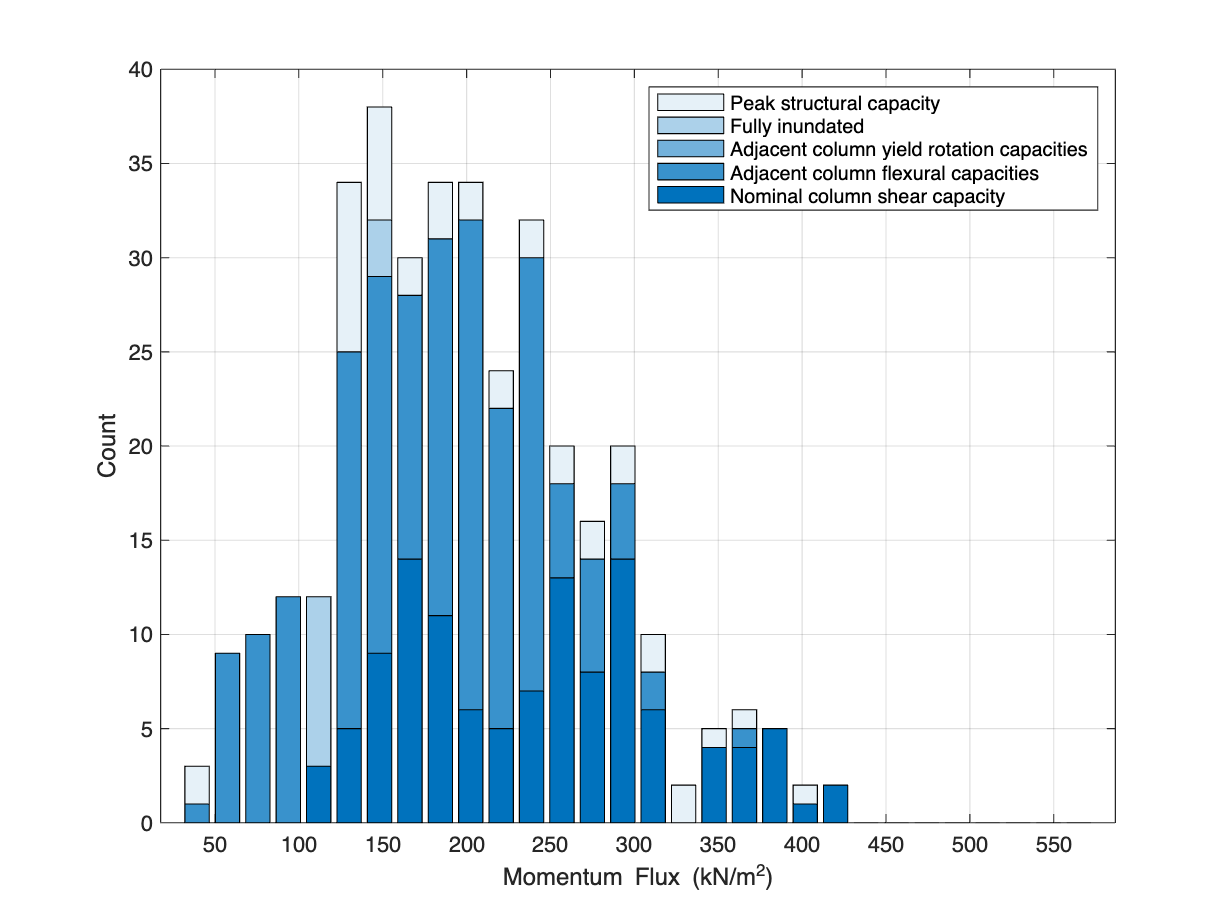

legend(Legend, 'Location', 'northeast');
xlabel('Momentum Flux (kN/m^2)')
title('')
exportgraphics(fig, fullfile(dirFigures, 'EDP_MF_A2_T1.png'), 'Resolution', 300);


fig = plotIMFailureDistribution(IM_damage, failure_mechanisms, A2_T2_Keys, numBins);

    {'column_shearNominal'                    }
    {'first_adjacent_columns_flexure_capacity'}
    {'first_adjacent_columns_yieldRotation'   }
    {'fully_inundated'                        }
    {'max_structural_capacity'                }



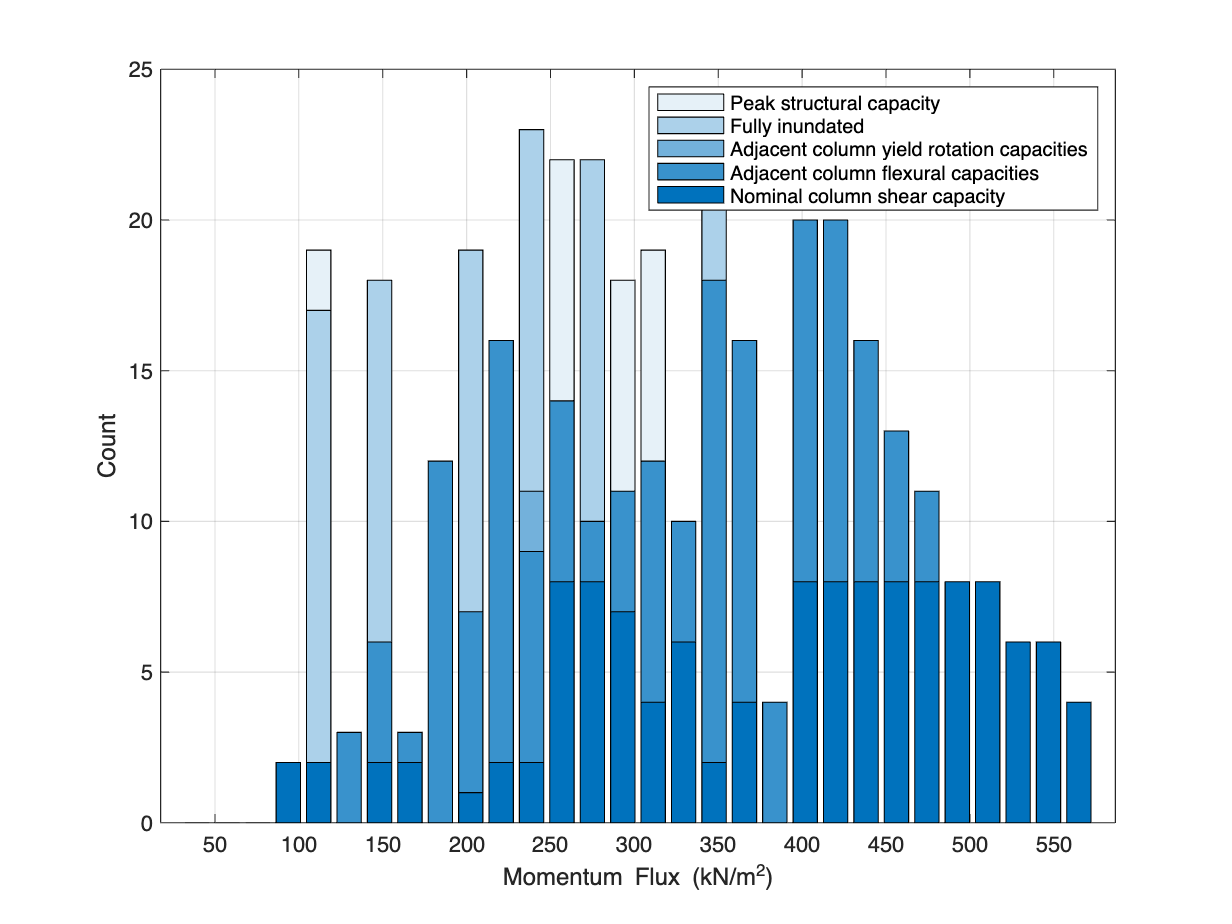

legend(Legend, 'Location', 'northeast');
xlabel('Momentum Flux (kN/m^2)')
title('')
exportgraphics(fig, fullfile(dirFigures, 'EDP_MF_A2_T2.png'), 'Resolution', 300);


fig = plotIMFailureDistribution(IM_damage, failure_mechanisms, A2_X_Keys, numBins);

    {'column_shearNominal'                    }
    {'first_adjacent_columns_flexure_capacity'}
    {'first_adjacent_columns_yieldRotation'   }
    {'fully_inundated'                        }
    {'max_structural_capacity'                }



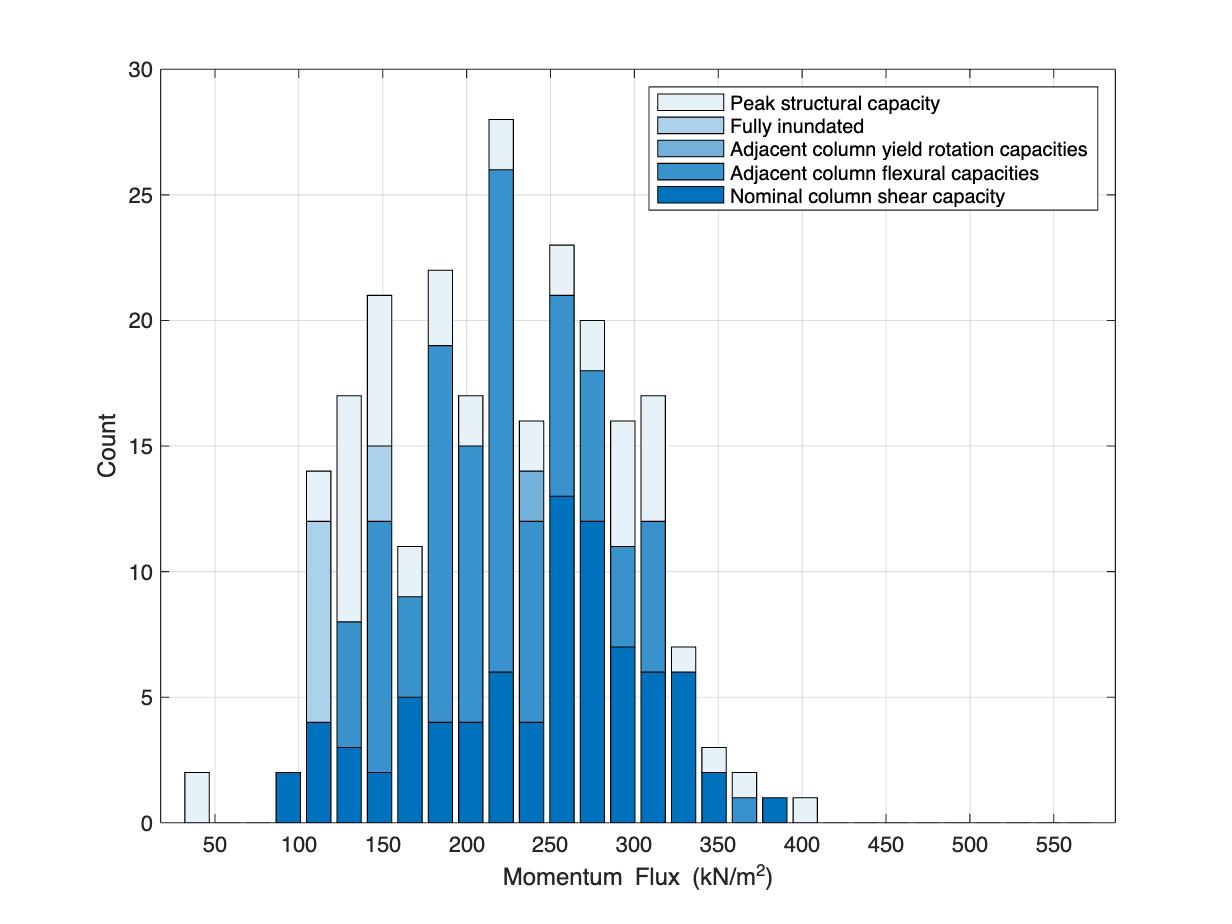

legend(Legend, 'Location', 'northeast');
xlabel('Momentum Flux (kN/m^2)')
title('')
exportgraphics(fig, fullfile(dirFigures, 'EDP_MF_A2_X.png'), 'Resolution', 300);


fig = plotIMFailureDistribution(IM_damage, failure_mechanisms, A2_Y_Keys, numBins);

    {'column_shearNominal'                    }
    {'first_adjacent_columns_flexure_capacity'}
    {'first_adjacent_columns_yieldRotation'   }
    {'fully_inundated'                        }
    {'max_structural_capacity'                }



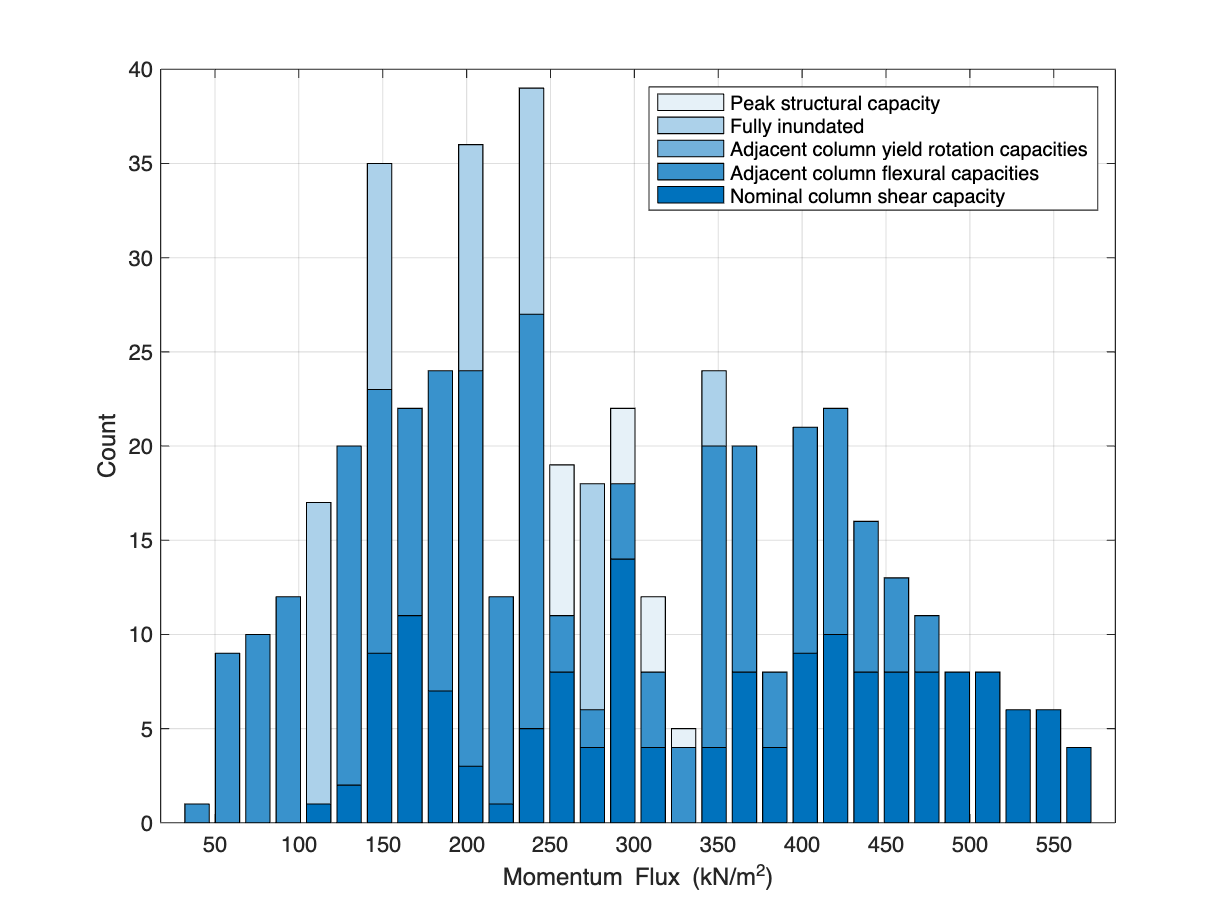

legend(Legend, 'Location', 'northeast');
xlabel('Momentum Flux (kN/m^2)')
title('')
exportgraphics(fig, fullfile(dirFigures, 'EDP_MF_A2_Y.png'), 'Resolution', 300);

fig = plotScenarioFailureStack(failure_mechanisms);
legend(Legend,'Location','southoutside')
title('')
exportgraphics(fig, fullfile(dirFigures, 'scenario_EDP_dis_X_Y_2F_3F_T1_T2.png'), 'Resolution', 300);
close(fig)

function [failure_mechanisms, dt_damage, IM_damage, PO_curve] = processClassDS5(classKeys, DIRECTORIES, objDS)
    % Convert classKeys into cell array of DS objects
    class_DS = cellfun(@(k) objDS(k), classKeys, 'UniformOutput', false);
    uniqueClasses = unique(classKeys); % in case some classes are counted twice for fragility

    % Initialize containers
    failure_mechanisms = containers.Map('KeyType', 'char', 'ValueType', 'any');
    dt_damage = containers.Map('KeyType', 'char', 'ValueType', 'any');
    IM_damage = containers.Map('KeyType', 'char', 'ValueType', 'any');
    PO_curve = containers.Map('KeyType', 'char', 'ValueType', 'any');
    
    % Iterate over each class
    for ii = 1:length(uniqueClasses)
        className = uniqueClasses{ii};

        % Store failure mechanisms
        failure_mechanisms(className) = values(class_DS{ii}.failureMechanism);

        % Store IM damage
        IM_damage(className) = class_DS{ii}.IMdamage;

        % Process dtDamage values
        dtDamage = values(class_DS{ii}.dtDamage);
        dtDamage = vertcat(dtDamage{:});
        dt_damage(className) = dtDamage;

        % Find directory index
        indx = find(cellfun(@(x) strcmp(x.Archetype, className), DIRECTORIES), 1);
        if isempty(indx)
            disp(['No matching class found for: ', className]);
            continue;
        end
        
        class_dir_results = DIRECTORIES{indx}.analysisOUT;
        scenarios = fieldnames(class_dir_results);

        % Store pushover drift curves
        POdrift = containers.Map('KeyType', 'char', 'ValueType', 'any');

        for jj = 1:length(scenarios)
            scn = scenarios{jj};
            OUT = load(class_dir_results.(scn));
            POdrift(scn) = OUT.analysisOUT.pushover_curve_GFdrift;
            clear OUT;
        end
        PO_curve(className) = POdrift;
    end
end

function [fig, leg] = plotScenarioFailureStack(failure_mechanisms)
    % Extract structure names (keys from failure_mechanisms)
    structureKeys = keys(failure_mechanisms);
    numStructures = length(structureKeys);
    
    % Extract scenario names from the first structure (assume all structures have the same scenarios)
    firstStructure = structureKeys{1};
    scenarioNames = failure_mechanisms(firstStructure);
    numScenarios = length(scenarioNames);
    
    % Identify unique failure mechanisms across all structures and scenarios
    allFailureMechanisms = values(failure_mechanisms);
    uniqueMechs = sort(unique(vertcat(allFailureMechanisms{:})));
    numMechs = length(uniqueMechs);

    % Colormap
    cmap = flipud(sky(numMechs));

    % Initialize data storage: rows (mechanisms), columns (scenarios)
    barData = zeros(numMechs, numScenarios);

    % Iterate over each structure
    for structIdx = 1:numStructures
        structName = structureKeys{structIdx};

        % Get failure mechanisms for this structure (cell array of length numScenarios)
        failureMechsStruct = failure_mechanisms(structName);

        % Iterate over scenarios within the structure
        for scnIdx = 1:numScenarios
            failureMechsScn = failureMechsStruct{scnIdx}; % Failure mechanisms for this scenario

            % Count occurrences of each failure mechanism
            for mechIdx = 1:numMechs
                mech = uniqueMechs{mechIdx};
                barData(mechIdx, scnIdx) = barData(mechIdx, scnIdx) + sum(strcmp(failureMechsScn, mech));
            end
        end
    end

    % Create figure
    fig = figure;
    hold on;

    % Plot stacked bars
    bars = bar(1:numScenarios, barData', 'stacked');
    for mechIdx = 1:numMechs
        bars(mechIdx).FaceColor = cmap(mechIdx, :);
    end

    % Formatting
    xlabel('Tsunami Scenarios: b/w = 0.1');
    ylabel('Number of Failures');
    title('Failure Mechanism Distribution Across Scenarios (All Structures)');
    xticks(1:numScenarios);
    Fr_values = 0.5 + 0.1 * (0:numScenarios-1);
    labels = arrayfun(@(n, fr) sprintf('Scn %d. Fr = %.1f', n, fr), 1:numScenarios, Fr_values, 'UniformOutput', false);
    xticklabels(labels);
    xtickangle(45); % Rotate labels for readability

    % Remove underscores from failure mechanism names
    cleanLegendNames = strrep(uniqueMechs, '_', ' ');

    % Create legend
    leg = legend(cleanLegendNames, 'Location', 'southeastoutside');

    box on;
    grid on;
    hold off;
end

function [fig, leg] = plotIMFailureDistribution(IM_damage, failure_mechanisms, classKeys, numBins)
    % Define number of bins for IM values
    if nargin < 4
        numBins = 30;
    end

    % IM values across classes
    IMdamageValues = values(IM_damage);
    damageValues = vertcat(IMdamageValues{:}); 

    % Bin edges
    binEdges = linspace(min(damageValues), max(damageValues), numBins+1);
    binCenters = (binEdges(1:end-1) + binEdges(2:end)) / 2; % Bin center for plotting

    % Unique failure mechanisms
    failureMechanisms = values(failure_mechanisms);
    uniqueMechs = sort(unique(vertcat(failureMechanisms{:}))); 
    numMechs = length(uniqueMechs);
    disp(uniqueMechs); % check with legend

    % colormap
    cmap = flipud(sky(numMechs));

    % Initialize data storage
    barData = zeros(numMechs, numBins);

    % Iterate over each class
    for ii = 1:length(classKeys)
        className = classKeys{ii};

        % Get failure mechanisms and IM values
        failureMechs = failure_mechanisms(className);
        IM_values = IM_damage(className);

        % Assign counts for each failure mechanism
        for mechIdx = 1:numMechs
            mech = uniqueMechs{mechIdx};

            % Get indices for this failure mechanism
            mechIdxs = strcmp(failureMechs, mech);

            % Count IM occurrences within bins
            binCounts = histcounts(IM_values(mechIdxs), binEdges);

            % Accumulate counts across classes
            barData(mechIdx, :) = barData(mechIdx, :) + binCounts;
        end
    end

    % Create figure
    fig = figure;
    hold on;

    % Plot each failure mechanism as a separate bar with assigned color
    bars = bar(binCenters, barData', 'stacked');
    for mechIdx = 1:numMechs
        bars(mechIdx).FaceColor = cmap(mechIdx, :);
    end

    % Formatting
    xlabel('IM','Interpreter','tex');
    ylabel('Count');
    title('Distribution of IM Values by Failure Mechanism');

    % Remove underscores from failure mechanism names
    cleanMechNames = strrep(uniqueMechs, '_', ' ');

    % Create legend and return legend handle
    leg = legend(cleanMechNames, 'Location', 'northeast');
    box on;
    grid on;
    hold off;
end

function [fig, leg] = plotFailureMechanismScatter(classKeys, dt_damage, IM_damage, PO_curve, failure_mechanisms, marker, fig)
    % Identify unique failure mechanisms
    failureMechanisms = values(failure_mechanisms);
    uniqueMechs = sort(unique(vertcat(failureMechanisms{:})));
    numMechs = length(uniqueMechs);

    % Colormap for failure mechanisms
    cmap = sky(numMechs);
    if nargin < 6
        marker = 'o';
    end

    % Create figure
    if nargin < 7
        fig = figure;
        hold on
    end

    % Ensure consistent legend colors by plotting invisible markers first
    legendHandles = gobjects(numMechs, 1);
    for mm = 1:numMechs
        legendHandles(mm) = scatter(nan, nan, 20, cmap(mm, :), 'filled', 'MarkerEdgeColor', 'k');
    end

    % Iterate over unique classes
    for ii = 1:length(classKeys)
        className = classKeys{ii};

        class_dtDamage = dt_damage(className);
        PO = PO_curve(className);
        PO = values(PO);
        FailMechs = failure_mechanisms(className);

        for jj = 1:length(PO) % Iterate over each scenario
            PO_scn = PO{jj};

            % Find index of failure mechanism in uniqueMechs
            mechIdx = find(strcmp(uniqueMechs, FailMechs{jj}));
            mechColor = cmap(mechIdx, :);

            if jj <= length(class_dtDamage)
                drift = abs(PO_scn(class_dtDamage(jj)-1, 1))*1e2;
                Vb = abs(PO_scn(class_dtDamage(jj)-1, 2));

                % Scatter plot for this failure mechanism with assigned color
                s = scatter(drift, Vb, 30, ...
                    'Marker', marker, ...
                    'MarkerFaceColor', mechColor, ...
                    'MarkerEdgeColor', 'k');
            end
        end
    end

    % Legend formatting
    cleanLegendNames = strrep(uniqueMechs, '_', ' '); % Remove underscores
    leg = legend(legendHandles, cleanLegendNames, 'Location', 'southeast');

    % Formatting
    xlabel('Ground Floor Drift: \Delta (%)', 'Interpreter', 'tex');
    ylabel('Base Shear: V_b (kN)', 'Interpreter', 'tex');
    grid on;
    box on;
end

function [fig, leg] = plotFailureMechanismScatter3D(uniqueClassKeys, dt_damage, IM_damage, PO_curve, failure_mechanisms)
    % Identify unique failure mechanisms
    failureMechanisms = values(failure_mechanisms);
    uniqueMechs = sort(unique(vertcat(failureMechanisms{:})));
    numMechs = length(uniqueMechs);

    % Colormap for failure mechanisms
    cmap = parula(numMechs);
    marker = 'o'; % Use 'o' for all markers

    % Create figure
    fig = figure;
    hold on
    
    % Ensure consistent legend colors by plotting invisible markers first
    legendHandles = gobjects(numMechs, 1);
    for mm = 1:numMechs
        legendHandles(mm) = scatter3(nan, nan, nan, 20, cmap(mm, :), 'filled', 'MarkerEdgeColor', 'k');
    end

    % Iterate over unique classes
    for ii = 1:length(uniqueClassKeys)
        className = uniqueClassKeys{ii};

        class_dtDamage = dt_damage(className);
        class_IMDamageValues = IM_damage(className);
        PO = PO_curve(className);
        PO = values(PO);
        FailMechs = failure_mechanisms(className);

        for jj = 1:length(PO) % Iterate over each scenario
            PO_scn = PO{jj};

            % Find index of failure mechanism in uniqueMechs
            mechIdx = find(strcmp(uniqueMechs, FailMechs{jj}));
            mechColor = cmap(mechIdx, :);

            if jj <= length(class_dtDamage)
                drift = abs(PO_scn(class_dtDamage(jj)-1, 1)); % X-axis (Drift)
                Vb = abs(PO_scn(class_dtDamage(jj)-1, 2));    % Y-axis (Base Shear)
                IMval = class_IMDamageValues(jj);             % Z-axis (IM Damage)

                % 3D Scatter plot
                scatter3(drift, Vb, IMval, 30, ...
                    'Marker', marker, ...
                    'MarkerFaceColor', mechColor, ...
                    'MarkerEdgeColor', 'k' ...
                    );
            end
        end
    end

    % Legend formatting
    cleanLegendNames = strrep(uniqueMechs, '_', ' '); % Remove underscores
    leg = legend(legendHandles, cleanLegendNames, 'Location', 'bestoutside');

    % Formatting
    xlabel('Ground Floor Drift (\Delta)', 'Interpreter', 'tex');
    ylabel('Base Shear: V_b (kN)', 'Interpreter', 'tex');
    zlabel('IM Damage', 'Interpreter', 'tex');
    grid on;
    box on;
    view(45, 30);
    hold off;
end